% Define constants
beta_values =   [0, 0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2, 2.125, 2.25, 2.375, 2.5, 2.625, 2.75, 2.875, 3, 3.125, 3.25, 3.375, 3.5, 3.625, 3.75, 3.875, 4, 4.125,4.25,4.375,4.5,4.625,4.75,4.875,5];
thresholds = [0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2];
data_dir = fullfile(pwd, 'bou/');
rng_list = (1:50);
% Step 1: Load all .mat files and combine into a single struct array
file_list = dir(fullfile(data_dir, '*.mat'));

scores = zeros(length(rng_list),length(beta_values),16,5);

for f = 1:length(beta_values)
    disp(beta_values(f)+"____________________________");

    for k = 1:16
       disp(k+"____________________________");

        % Convert each entry_struct to the desired format
        for j = 1:10
            [train_x,train_y,test_x,test_y] = splitData(database_seizure{f,:},database_normal{f,:},rng_list(j));
            [test_x,test_y] = extractFeatures(test_x,test_y,k);
            [train_x,train_y] = extractFeatures(train_x,train_y,k);
            
        
            % Train model with class weights
            svmModel = trainWeightedSVM(train_x, train_y,rng_list(j));
            
        
            % Evaluate on test set
            [testAccuracy, sensitivity,specificity,precision,f1score] = evaluateModel(svmModel, test_x, test_y);
            scores(j,f,k,:) = [testAccuracy,sensitivity,specificity,precision,f1score];
    
    
        end
    end
end

figHandles = findall(groot, 'Type', 'figure');
    if ~isempty(figHandles)
        close(figHandles);
    end

plotHeatmap(scores(:,:,1),"accuracy",beta_values,rng_list);
plotHeatmap(scores(:,:,2),"sensitivity",beta_values,rng_list);
plotHeatmap(scores(:,:,3),"specificity",beta_values,rng_list);
plotHeatmap(scores(:,:,4),"precision",beta_values,rng_list);
plotHeatmap(scores(:,:,5),"f1score",beta_values,rng_list);
function plotHeatmap(data, titleStr, xLabel, yLabel)
    % PLOTHEATMAP Creates a heatmap from any m×n array with values in [0, 1].
    % Inputs:
    %   - data: m×n array with values between 0 and 1
    %   - titleStr: String for the figure title
    %   - xLabel: 1×n cell/string array
    %   - yLabel: 1×m cell/string array
    data = squeeze(data);
    [m, n] = size(data);

    figure('Name', titleStr, 'NumberTitle', 'off');
    drawnow;

    % Plot
    h = heatmap(data, ...
        'ColorbarVisible', 'on', ...
        'GridVisible', 'off');
    colormap(gca, 'autumn')

    title(titleStr);
    h.XLabel = 'Beta value';
    h.YLabel = 'RNG';
    
    if length(xLabel) == n
        h.XDisplayLabels = xLabel;
    end
    if length(yLabel) == m
        h.YDisplayLabels = yLabel;
    end
end







beta_values =   [0, 0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2, 2.125, 2.25, 2.375, 2.5, 2.625, 2.75, 2.875, 3, 3.125, 3.25, 3.375, 3.5, 3.625, 3.75, 3.875, 4, 4.125,4.25,4.375,4.5,4.625,4.75,4.875,5];
rng_list = (1:10);

thresholds = [0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2];
plotHeatmap(scores(1:10,30,:,1),"accuracy",thresholds,rng_list);
plotHeatmap(scores(1:10,21,:,1),"accuracy",thresholds,rng_list);
plotHeatmap(scores(1:10,3,:,1),"accuracy",thresholds,rng_list);



function svmModel = trainWeightedSVM(XTrain, YTrain,rng_num)
    % Train SVM with class weights
    rng(rng_num)

    
    % Calculate class weights
   
    costMatrix = [0, 1; 1, 0];
    
    
   
    
    % Hyperparameter optimization (optional)
    try
       
        % Define wider and logarithmic search space
        hyperparameters = [
            optimizableVariable('BoxConstraint', [1e-3, 1e4], 'Transform', 'log')
            optimizableVariable('KernelScale', [1e-3, 1e4], 'Transform', 'log')
        ];

        opts = struct(...
            'Optimizer', 'bayesopt', ...
            'MaxObjectiveEvaluations', 100, ...
            'AcquisitionFunctionName', 'expected-improvement-plus', ...
            'ShowPlots', false, ...  
            'Verbose', 0, ...
            'Repartition', true);
        
        svmModel = fitcsvm(XTrain, YTrain, ...
            'KernelFunction', 'gaussian', ...
            'KernelScale','auto',...
            'IterationLimit',1e20,...
            'Standardize', true, ...
            'ClassNames', {'Non-Seizure', 'Seizure'}, ...
            'Cost', costMatrix, ...
            'Verbose', 0, ...
            'Solver', 'SMO', ...
            'OptimizeHyperparameters', hyperparameters, ...
            'HyperparameterOptimizationOptions', opts);
        
        
    catch e
        disp('Hyperparameter optimization failed. Using default model.');
        disp(['Error: ' e.message]);
    end
end




function [train_x,train_y,test_x,test_y] = splitData(seizures, nonSeizures,rng_num)
    rng(rng_num);

    indicies_seizures = randperm(length(seizures));
    indicies_nonSeizure = randperm(length(nonSeizures));

    train_x = seizures(indicies_seizures(1:0.8*length(indicies_seizures)));
    test_x = seizures(indicies_seizures(0.8*length(indicies_seizures)+1:end));

    train_x = [train_x,nonSeizures(indicies_nonSeizure(1:0.8*length(indicies_nonSeizure)))];
    test_x = [test_x,nonSeizures(indicies_nonSeizure(0.8*length(indicies_nonSeizure)+1:end))];
    train_y =  [ones(1, 400), zeros(1, 400)];
    test_y = [ones(1, 100), zeros(1, 100)];
    

end

function [X, labels] = extractFeatures(data, y,threshold)
    % Extracts RQA features from EEG struct array across bands.
    % Input:
    %   data - Struct array with fields RQA_A, RQA_B, RQA_D, RQA_T
    %   y    - Vector of seizure labels (0 = Non-Seizure, 1 = Seizure)
    % Output:
    %   X      - Numeric feature matrix (n_segments × (n_rqa_features * n_bands))
    %   labels - Categorical seizure labels ('Non-Seizure', 'Seizure')

    n_segments = length(data);
    n_rqa_features = 13; % rr, det, l, lam, tt, hor, ah, lmax, vmax, hmax, t2_v, t2_h, entr
    n_bands = 4; % RQA_A, RQA_B, RQA_D, RQA_T

    % Initialize feature matrix
    X = zeros(n_segments, n_rqa_features * n_bands);
    
    % Initialize labels from input y
    labels = categorical(y, [0 1], {'Non-Seizure', 'Seizure'});

    % RQA feature fields
    rqa_fields = {'rr', 'det', 'l', 'lam', 'tt', 'hor', 'ah', 'lmax', ...
                  'vmax', 'hmax', 't2_v', 't2_h', 'entr'};

    for i = 1:n_segments
        % Initialize feature vector for this segment
        features = zeros(1, n_rqa_features * n_bands);
        
        % Extract RQA features for each band
        rqa_data = {data{i}.RQA_A(threshold), data{i}.RQA_B(threshold), data{i}.RQA_D(threshold), data{i}.RQA_T(threshold)};
        
        for j = 1:n_bands
            band_data = rqa_data{j}; % Single struct for this band
            % Compute feature index offset for this band
            offset = (j-1) * n_rqa_features;
            for k = 1:n_rqa_features
                features(offset + k) = band_data.(rqa_fields{k});
            end
        end
        
        X(i, :) = features;
    end
end


function [testAccuracy, sensitivity,specificity,precision,f1score] = evaluateModel(svmModel, XTest, YTest)
    % Evaluate model on test set
    [~, YTestScores] = predict(svmModel, XTest);
    seizureIdx = strcmp(svmModel.ClassNames, 'Seizure');
    YTestPred = categorical(YTestScores(:, seizureIdx) >= 0, ...
                            [0 1], {'Non-Seizure', 'Seizure'});
    YTestPred = YTestPred';
    testAccuracy = sum(YTestPred == YTest) / numel(YTest);
    disp(['Test Accuracy: ' num2str(testAccuracy * 100, '%.2f') '%']);
    
    TP = sum(YTestPred == 'Seizure' & YTest == 'Seizure');
    FP = sum(YTestPred == 'Seizure' & YTest == 'Non-Seizure');
    TN = sum(YTestPred == 'Non-Seizure' & YTest == 'Non-Seizure');
    FN = sum(YTestPred == 'Non-Seizure' & YTest == 'Seizure');
    
    sensitivity = TP / (TP + FN) * 100;
    specificity = TN / (TN + FP) * 100;
    precision = TP / (TP + FP) * 100;
    f1score = 2 * (precision * sensitivity) / (precision + sensitivity);
    
    disp(['Sensitivity (Seizure Recall): ' num2str(sensitivity, '%.2f') '%']);
    disp(['Specificity: ' num2str(specificity, '%.2f') '%']);
    disp(['Precision: ' num2str(precision, '%.2f') '%']);
    disp(['F1 Score: ' num2str(f1score, '%.2f')]);
    
    % Plot confusion matrix
    %figure;
    %cm = confusionchart(YTest, YTestPred);
    %cm.Title = 'SVM Confusion Matrix';
    %cm.RowSummary = 'row-normalized';
    %cm.ColumnSummary = 'column-normalized';
    
end

function analyzeFeatureImportance(svmModel, XTest, YTest)
    % Analyze feature importance using multiple methods
    % Input:
    %   svmModel - Trained SVM model
    %   XTest    - Test feature matrix (n_segments × (n_rqa_features * n_signals))
    %   YTest    - Test labels (categorical, 'Non-Seizure' or 'Seizure')
    % Output:
    %   Plots and displays feature importance for individual features and groups
    try
        % Define feature names
        rqa_fields = {'rr', 'det', 'l', 'lam', 'tt', 'hor', 'ah', 'lmax', ...
                      'vmax', 'hmax', 't2_v', 't2_h', 'entr'};
        signals = {'A', 'B', 'D', 'T'};
        numMetrics = length(rqa_fields); % 13
        numSignals = length(signals);    % 4
        
        % Create feature names (signal + metric)
        allFeatureNames = cell(1, numMetrics * numSignals);
        idx = 1;
        for s = 1:numSignals
            for m = 1:numMetrics
                allFeatureNames{idx} = sprintf('%s_%s', signals{s}, rqa_fields{m});
                idx = idx + 1;
            end
        end
        
        % Method 1: Permutation importance with multiple shuffles
        disp('Calculating feature importance via multiple permutations...');
        numRepeats = 5; % Multiple permutations for reliability
        totalFeatures = size(XTest, 2); % Should be 13 * 4 = 52
        featureImportance = zeros(totalFeatures, 1);
        
        % Evaluate baseline performance (AUC)
        [YTestPred, YTestScores] = predict(svmModel, XTest);
        seizureIdx = find(strcmp(svmModel.ClassNames, 'Seizure'));
        [~, ~, ~, baselineAUC] = perfcurve(YTest, YTestScores(:, seizureIdx), 'Seizure');
        baselineAUC = baselineAUC(end); % Get AUC value
        
        % Compute permutation importance
        for i = 1:totalFeatures
            importancePerRep = zeros(numRepeats, 1);
            for rep = 1:numRepeats
                XTestPerm = XTest;
                XTestPerm(:, i) = XTestPerm(randperm(size(XTestPerm, 1)), i);
                [~, permScores] = predict(svmModel, XTestPerm);
                [~, ~, ~, permAUC] = perfcurve(YTest, permScores(:, seizureIdx), 'Seizure');
                importancePerRep(rep) = baselineAUC - permAUC;
            end
            featureImportance(i) = mean(importancePerRep);
        end
        
        % Method 2: Feature group importance
        disp('Calculating feature group importance...');
        groupImportance = zeros(numMetrics, numSignals);
        
        for m = 1:numMetrics
            for s = 1:numSignals
                % Get feature index for this signal and metric
                featureIdx = (s-1) * numMetrics + m;
                
                % Permute the feature
                XTestPerm = XTest;
                permIndices = randperm(size(XTestPerm, 1));
                XTestPerm(:, featureIdx) = XTestPerm(permIndices, featureIdx);
                
                [~, permScores] = predict(svmModel, XTestPerm);
                [~, ~, ~, permAUC] = perfcurve(YTest, permScores(:, seizureIdx), 'Seizure');
                groupImportance(m, s) = baselineAUC - permAUC;
            end
        end
        
        % Plot top individual features
        [sortedImportance, sortedIndices] = sort(featureImportance, 'descend');
        topFeatures = sortedIndices(1:min(10, length(sortedIndices)));
        
        figure;
        bar(sortedImportance(1:10));
        xlabel('Feature Rank');
        ylabel('Importance Score (AUC Drop)');
        title('Top 10 Most Important Individual Features');
        xticks(1:10);
        xticklabels(allFeatureNames(topFeatures));
        xtickangle(45);
        
        % Plot feature group importance as a heatmap
        figure;
        heatmap(signals, rqa_fields, groupImportance);
        title('Feature Group Importance');
        xlabel('Signal');
        ylabel('RQA Metric');
        
        % Check if RR is constant
        disp('Checking if RR metric is constant across samples...');
        rrIndices = 1:numMetrics:totalFeatures; % Indices of RR for each signal
        rrStdDevs = std(XTest(:, rrIndices));
        rrMeans = mean(XTest(:, rrIndices));
        rrCV = rrStdDevs ./ rrMeans * 100; % Coefficient of variation (%)
        
        disp('RR Statistics:');
        disp(['Mean Std Dev: ' num2str(mean(rrStdDevs))]);
        disp(['Max Std Dev: ' num2str(max(rrStdDevs))]);
        disp(['Mean CV(%): ' num2str(mean(rrCV))]);
        
        if mean(rrStdDevs) < 1e-6
            disp('WARNING: RR appears to be nearly constant across samples.');
            disp('This may indicate an issue with the feature extraction.');
        end
        
        % Display top 5 features
        disp('Top 5 most important features:');
        for i = 1:min(5, length(sortedIndices))
            disp([num2str(i) '. ' allFeatureNames{sortedIndices(i)} ': ' ...
                  num2str(sortedImportance(i), '%.4f')]);
        end
        
    catch e
        disp('Feature importance analysis failed.');
        disp(['Error: ' e.message]);
        disp('Stack trace:');
        disp(getReport(e));
    end
end

disp()
function correlated_features = findCorrelatedFeatures(XTrain, rqa_fields, n_bands)
    % Compute correlation matrix for RQA features across bands
    n_features = length(rqa_fields) * n_bands;
    corr_matrix = corr(XTrain);
    correlated_features = {};
    threshold = 0.8; % Correlation threshold
    
    for i = 1:n_features
        for j = i+1:n_features
            if abs(corr_matrix(i,j)) > threshold
                band_i = ceil(i / length(rqa_fields));
                field_i = rqa_fields{mod(i-1, length(rqa_fields))+1};
                band_j = ceil(j / length(rqa_fields));
                field_j = rqa_fields{mod(j-1, length(rqa_fields))+1};
                correlated_features{end+1} = sprintf('%s (band %d) vs. %s (band %d): %.2f', ...
                                                    field_i, band_i, field_j, band_j, corr_matrix(i,j));
            end
        end
    end
    disp('Highly correlated features (|ρ| > 0.8):');
    disp(correlated_features');
end

scores(:,:,:,1) = scores(:,:,:,1)*100;



% Define metric names for clarity
metricNames = {'Accuracy','Sensitivity', 'Specificity', 'Precision', 'F1-Score'};

% Preallocate matrix for mean metrics
metricsMeans = zeros(size(scores,2),size(scores, 3), length(metricNames));

% Loop over beta values
for j = 1 : size(scores,2)
    for i = 1:size(scores, 3)
        % Compute mean and standard deviation across seeds (dimension 1)
        means = squeeze(mean(scores(1:10,j, i, :), 1)); % 1 x 4 vector
        stds = squeeze(std(scores(1:10,j, i, :), [], 1)); % 1 x 4 vector
        
        % Store means and display results
        metricsMeans(j, i, :) = means;
        fprintf('Beta = %.2f:\n', beta_values(i));
        for m = 1:length(metricNames)
            fprintf('  %s: Mean = %.2f, Std = %.2f\n', ...
                    metricNames{m}, means(m), stds(m));
        end
        fprintf('\n');
    end
end



% Plot mean metrics vs. beta values
figure;
plot(thresholds, squeeze(metricsMeans(20,:,:)), '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Beta Value');
ylabel('Mean Metric Value (%)');
title('Mean Performance Metrics vs. Beta Value');
legend(metricNames, 'Location', 'best');
grid on;
set(gca, 'FontSize', 12);

maxThresholds = zeros(length(beta_values),1);
maxThresholdsIdx = zeros(length(beta_values),1);
for i = 1 : length(beta_values)
    results = squeeze(metricsMeans(i,:,5));
    [maxValue, idx] = max(results);
    maxThresholdsIdx(i) = idx;
    maxThresholds(i) = maxValue;
end

% Plot mean metrics vs. beta values
figure;
plot(beta_values, squeeze(maxThresholds), '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Beta Value');
ylabel('Mean Metric Value (%)');
title('Mean Performance Metrics vs. Beta Value');
grid on;
set(gca, 'FontSize', 12);

% Plot mean metrics vs. beta values
figure;
plot(beta_values, squeeze(maxThresholdsIdx), '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Beta Value');
ylabel('Mean Metric Value (%)');
title('Mean Performance Metrics vs. Beta Value');
grid on;
set(gca, 'FontSize', 12);

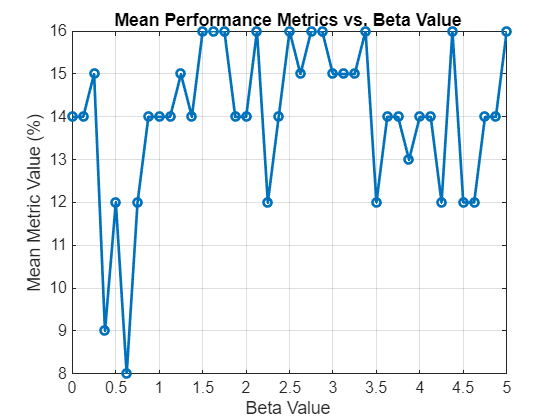



% Define metric names for clarity

% Preallocate matrix for mean metrics
metricsMeans = zeros(size(scores, 3), length(metricNames));

means = zeros();
% Loop over beta values
for i = 1:size(scores, 3)
    % Compute mean and standard deviation across seeds (dimension 1)
    means = squeeze(mean(scores(1:10,9, i, :), 1)); % 1 x 4 vector
    stds = squeeze(std(scores(1:10,9, i, :), [], 1)); % 1 x 4 vector
    
    % Store means and display results
    metricsMeans(i, :) = means;

end

% Plot mean metrics vs. beta values
figure;
plot(thresholds, metricsMeans, '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Beta Value');
ylabel('Threshold MAD');
title('Optimal threshold for each beta');
legend(metricNames, 'Location', 'best');
grid on;
set(gca, 'FontSize', 12);